## **Resolución de una derivada/integral**


$$f=x^3 +2x^2 -5x+1$$


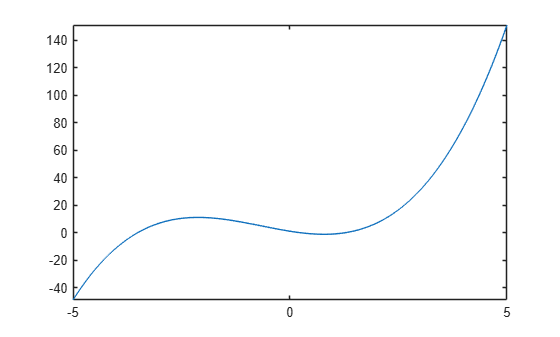

syms x
f = x^3 + 2*x^2 - 5*x + 1;
fplot(f)

### Derivada

df = diff(f, x)

$$df = 3\,x^{2}+4\,x-5$$

### Integral

F = int(f, x)

$$F = \frac{x^{4}}{4}+\frac{2\,x^{3}}{3}-\frac{5\,x^{2}}{2}+x$$

## Superficie

 $F\left(x,y\right)=\sin \left(x\right)*\cos \left(y\right)$  sobre [-5 5]x[-5 5]

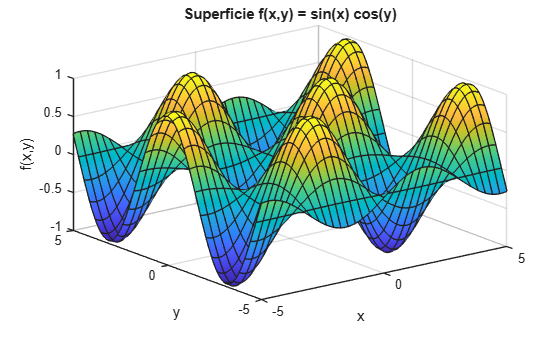

syms x y
f(x,y) = sin(x).*cos(y);    % define función simbólica
figure
fsurf(f, [-5 5 -5 5])       % grafica la superficie en el dominio dado

title('Superficie f(x,y) = sin(x) cos(y)')
xlabel('x'), ylabel('y'), zlabel('f(x,y)')
grid on

Curva paramétrica en 3D con fplot3

### Curva paramétrica: x(t)=sin(t), y(t)=cos(t), z(t)=t/2 para t en [-10,10]

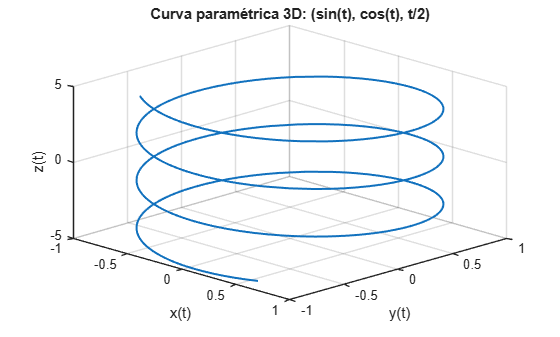

syms t
xt = sin(t);
yt = cos(t);
zt = t/2;
figure
fplot3(xt, yt, zt, [-10 10], 'LineWidth', 1.5)  % curva 3D
grid on
title('Curva paramétrica 3D: (sin(t), cos(t), t/2)')
xlabel('x(t)'), ylabel('y(t)'), zlabel('z(t)')
view(45,30)  % ángulo de cámara